**Breakpoints and Debugging **

I explored the use of breakpoints in MATLAB to analyze a program’s behavior in detail. This process allowed me to inspect variables, evaluate expressions, and identify issues in real-time, ultimately deepening my understanding of code execution.

Breakpoints in MATLAB are intentional stopping points in a program. These pauses allow me to examine the current state of variables and program flow, ensuring everything behaves as expected. MATLAB offers two types of breakpoints: **standard breakpoints**, which pause execution whenever a specified line is reached, and **conditional breakpoints**, which add an evaluation condition to the standard breakpoint.

By using the `dbstop` command, I could set breakpoints programmatically. For instance, I created a breakpoint on a specific line using `dbstop in myfile at 10` or set a conditional breakpoint with `dbstop in myfile at 10 if x > 5`. This flexibility gave me precise control over the program’s execution and helped me focus on the parts of the code that required scrutiny.

I found placing breakpoints in the MATLAB Editor to be straightforward. A simple click next to the line number added a breakpoint, turning the icon red for standard breakpoints or yellow for conditional ones. When debugging more extensive programs, disabling or clearing breakpoints became crucial to maintain focus. Using commands like `dbclear` or the Editor’s toolbar options allowed me to manage breakpoints efficiently.

**Debugging Techniques**

Once the program paused at a breakpoint, I inspected the variables in the workspace. This was invaluable for understanding how data flowed through my program. Using commands like `dbstep` to step through the code line-by-line or `dbcont` to continue execution until the next breakpoint provided a structured way to trace the program.

MATLAB also supports debugging Java code invoked by MATLAB itself. I explored this by enabling JVM debugging mode, attaching a Java debugger, and analyzing Java classes executed during MATLAB runtime. While this was more advanced, it opened up possibilities for integrating MATLAB with Java-based components.

% Debugging Example: Factorial Calculation with Visualization

% Input number for factorial calculation
n = 5; % You can change this value to test with other numbers
factorial_result = 1; % Initialize factorial result

% Initialize variables to store intermediate results for visualization
iteration = 1:n;
factorial_values = zeros(1, n);

% Loop to calculate factorial
for i = 1:n
    factorial_result = factorial_result * i; % Update result
    factorial_values(i) = factorial_result; % Store intermediate result
end

% Display final result
disp(['Factorial of ', num2str(n), ' is ', num2str(factorial_result)]);

Factorial of 5 is 120



% Create a table to summarize the calculation process
factorial_table = table(iteration', factorial_values', ...
    'VariableNames', {'Iteration', 'Factorial_Value'});

% Display the table
disp('Factorial Calculation Process:');

Factorial Calculation Process:


disp(factorial_table);

    Iteration    Factorial_Value
    _________    _______________

        1                1      
        2                2      
        3                6      
        4               24      
        5              120      



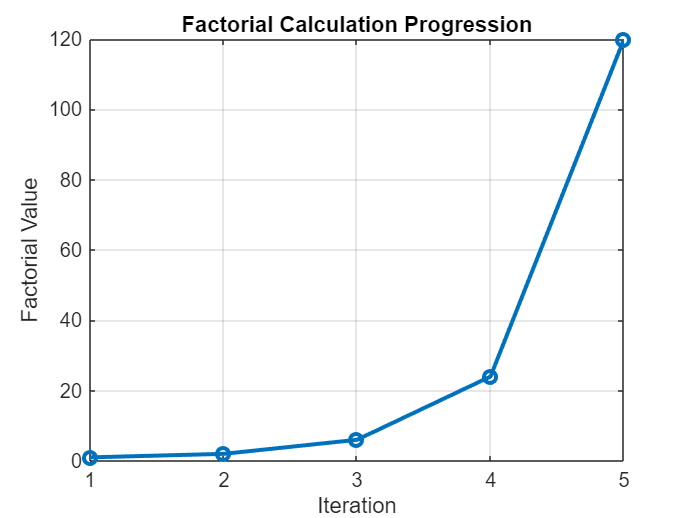


% Plot the progression of factorial calculation
figure;
plot(iteration, factorial_values, '-o', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Factorial Value');
title('Factorial Calculation Progression');
grid on;